clear;
close all;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%% MiniProjStarterFile.mlx
%%%% Cory Budischak
%%%% 11-3-23
%%%%
%%%% This code allows the user to filter COVID data in different ways
%%%% and visualize the results
%%%% Requires usCovidData.mat to run
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

load usCovidData.mat
%set axis font size...you may want to turn this down to generate plots for
%your paper
set(0,'defaultAxesFontSize',14)
%%data is cumulative now...convert to daily
cases(1)=0;
casesD=zeros(size(cases));
for i=1:length(cases)
    if i==1
        casesD(i)=cases(i);
    else
        casesD(i)=cases(i)-cases(i-1);
    end
end

%Make figure look better and plot original data
f=figure();
set(f,'Units','normalized','Position',[0 0 2 2]);
plot(date1,casesD, '-b')
ax=gca;



%Generate average filter and use conv to generate output
displayfilts=true;
AvgFiltLength1="5";
hn1=ones(str2double(AvgFiltLength1),1)*1/str2double(AvgFiltLength1);
if displayfilts
    disp("First filter")
    disp(hn1)
end

First filter


    0.2000
    0.2000
    0.2000
    0.2000
    0.2000



yn1=conv(casesD, hn1,"same");
%plot filtered output (yn1) on same graph as original data
hold on;
plot(date1,yn1,'-r',"LineWidth", 3);
legend(["Original" "Filtered"])

%repeat for 2nd filter
AvgFiltLength2="28";
hn2=ones(str2double(AvgFiltLength2),1)*1/str2double(AvgFiltLength2);
if displayfilts
    disp("Second filter")
    disp(hn2)
end

Second filter


    0.0357
    0.0357
    0.0357
    0.0357
    0.0357
    0.0357
    0.0357
    0.0357
    0.0357
    0.0357
    0.0357
    0.0357
    0.0357
    0.0357
    0.0357
    0.0357
    0.0357
    0.0357
    0.0357
    0.0357
    0.0357
    0.0357
    0.0357
    0.0357
    0.0357
    0.0357
    0.0357
    0.0357



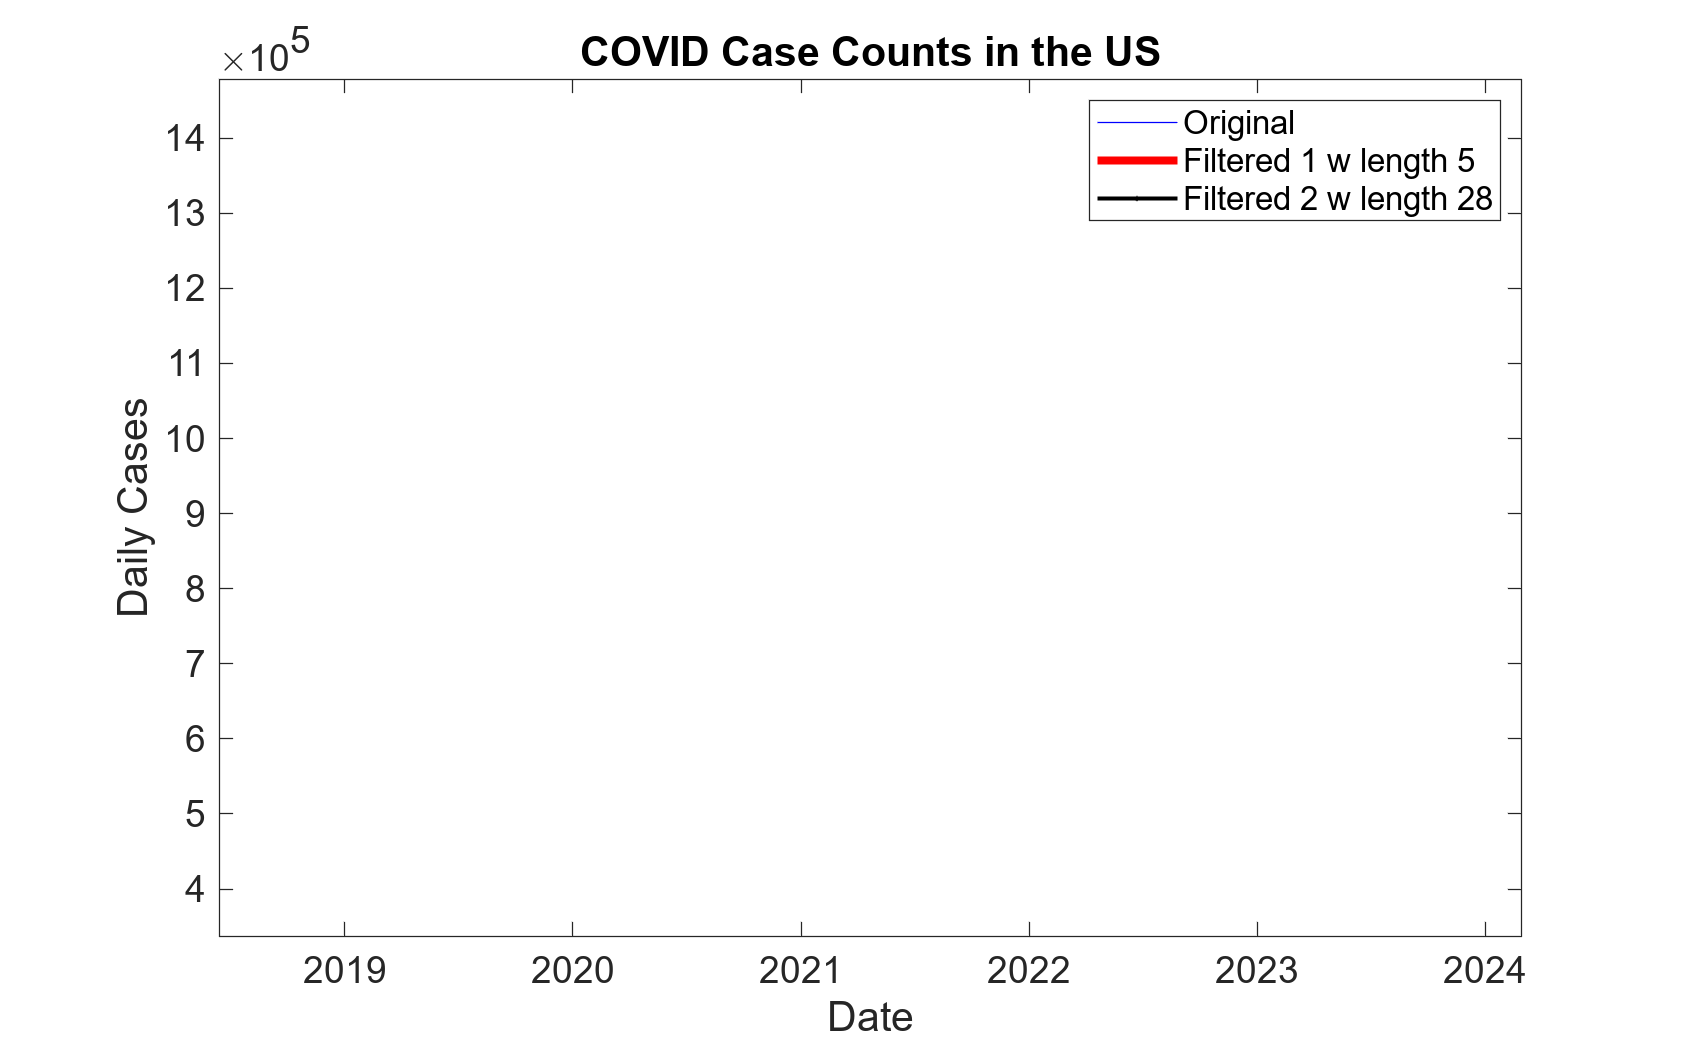

yn2=conv(casesD, hn2,"same");
hold on;
plot(date1,yn2,'.-k',"LineWidth", 1.5);
legend(["Original" strcat("Filtered 1 w length ",AvgFiltLength1) strcat("Filtered 2 w length ",AvgFiltLength2)])
title('COVID Case Counts in the US')
xlabel('Date')
ylabel('Daily Cases')
hold off;

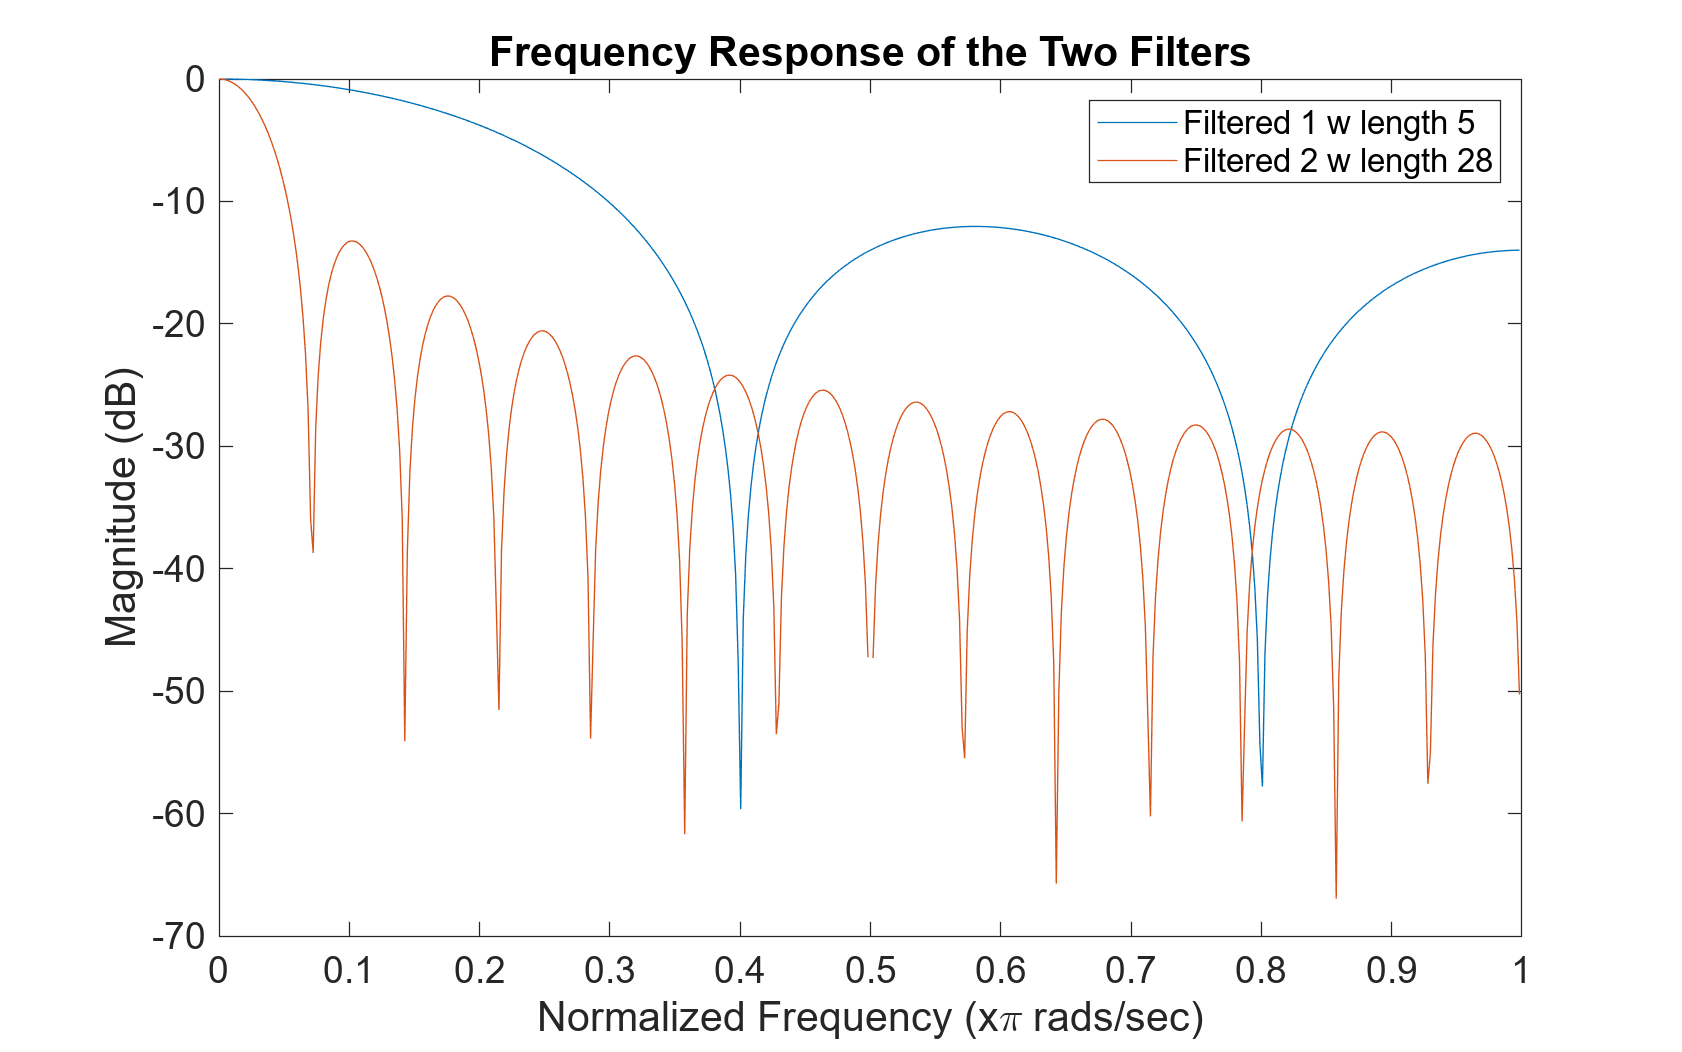

%Plot the frequency response of both filters
f=figure();
set(f,'Units','normalized','Position',[0 0 2 2]);
[response1, Omega1]=freqz(hn1);
[response2, Omega2]=freqz(hn2);
plot(Omega1/pi,20*log10(abs(response1)),Omega1/pi,20*log10(abs(response2)))
title('Frequency Response of the Two Filters');
xlabel("Normalized Frequency (x\pi rads/sec)");
ylabel("Magnitude (dB)")
legend([strcat("Filtered 1 w length ",AvgFiltLength1) strcat("Filtered 2 w length ",AvgFiltLength2)]);

## Fourier Transforms

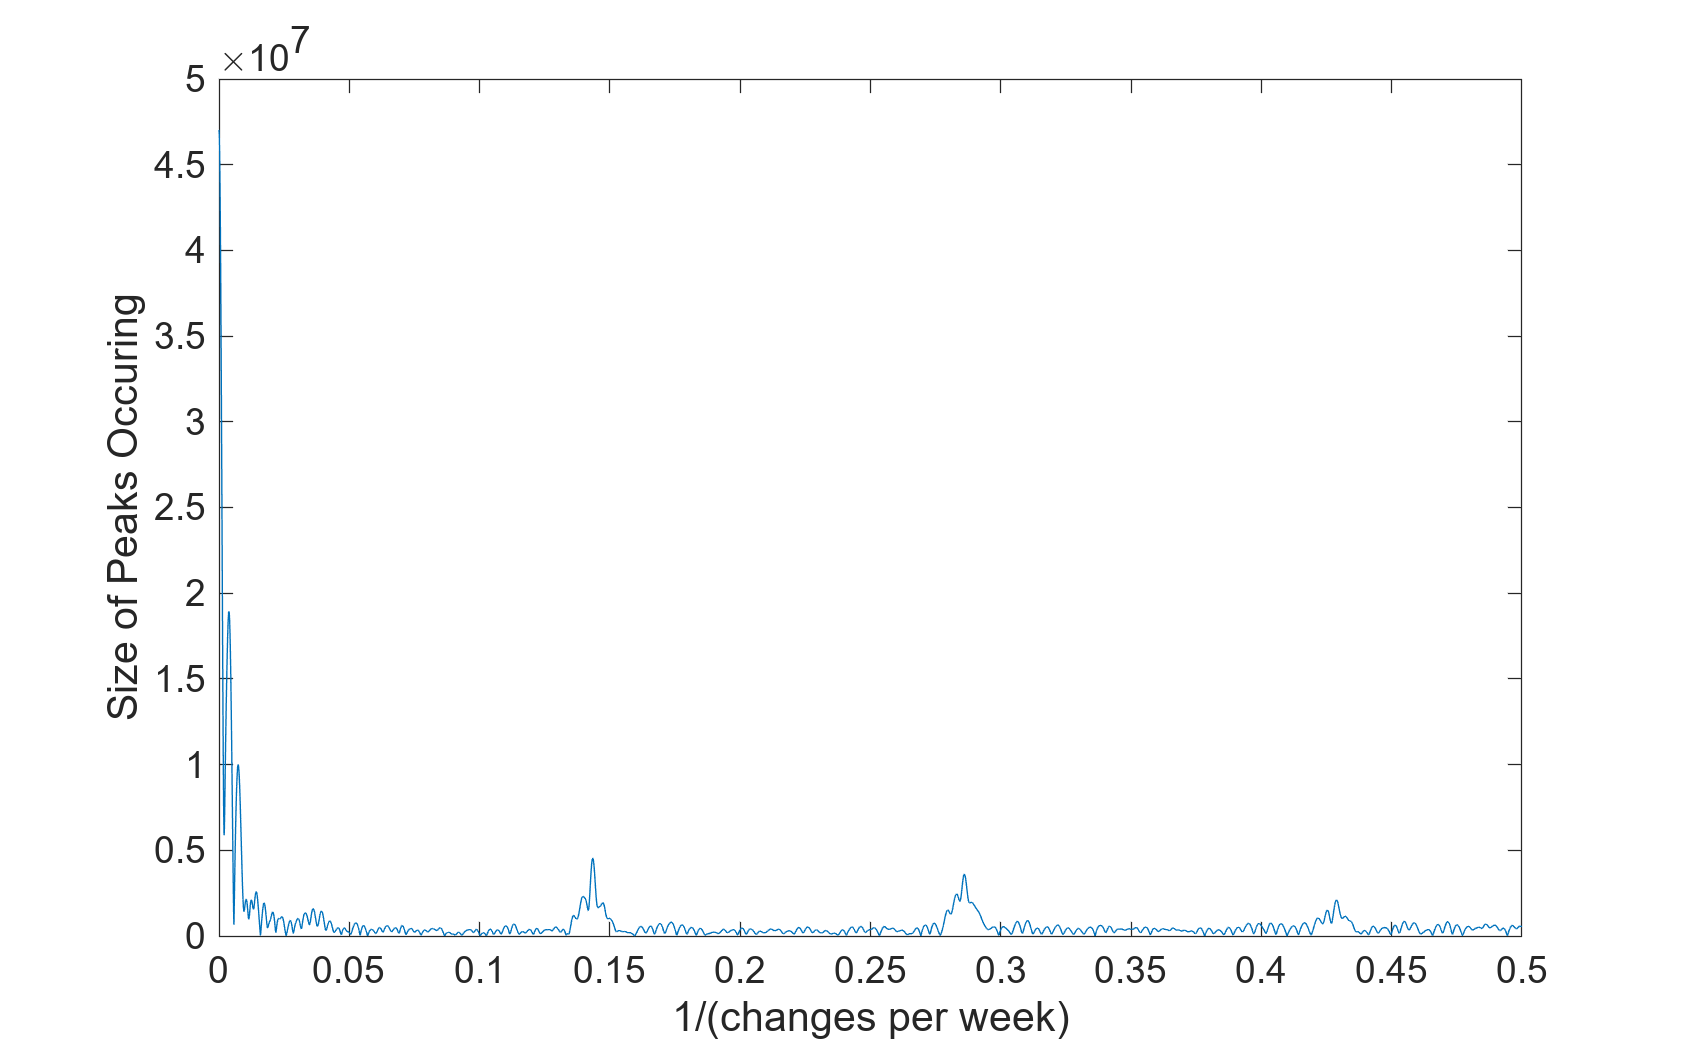

%myFFT(casesD,1/(3600*24)) % Hz
myFFT(casesD,1)
ylabel("Size of Peaks Occuring")
xlabel("1/(changes per week)")